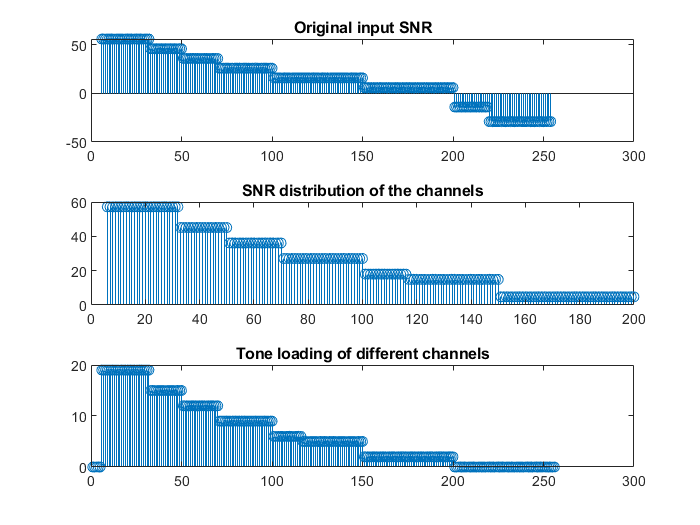

The power deviation is 0.074077


t=1:256; % Tone loading table not yet used.
snr=SPN_to_SNR_converter(); % Get the SNR table
b=basic_fine_gains(snr); % Get the adaptive bit loading

g_array=[b.pdiff];
disp(g_array);

  Columns 1 through 7

         0         0         0         0         0    1.2121    1.2121

  Columns 8 through 14

    1.2121    1.2121    1.2121    1.2121    1.2121    1.2121    1.2121

  Columns 15 through 21

    1.2121    1.2121    1.2121    1.2121    1.2121    1.2121    1.2121

  Columns 22 through 28

    1.2121    1.2121    1.2121    1.2121    1.2121    1.2121    1.2121

  Columns 29 through 35

    1.2121    1.2121    1.2121    1.2121   -0.8222   -0.8222   -0.8222

  Columns 36 through 42

   -0.8222   -0.8222   -0.8222   -0.8222   -0.8222   -0.8222   -0.8222

  Columns 43 through 49

   -0.8222   -0.8222   -0.8222   -0.8222   -0.8222   -0.8222   -0.8222

  Columns 50 through 56

   -0.8222    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426

  Columns 57 through 63

    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426

  Columns 64 through 70

    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426    0.1426

  Columns 71 through 77

    1.09

b=[b.nbits_rounded]; % Get only the number of rounded bits in the channel
%t = [7 14 21 4 11 18 1 8 15 22 5 12 19 2 9 16 23 6 13 20 3 10 17]; % Tone ordering table
%b = [0 1 2 4 2 3 2 5 0 2 0 2 7 1 6 3 8 2 9 0 2 12 2] % Bits in each channel
[~,Nsc] = size(b); % Number of sub-carriers
data = creverb1(Nsc); % PRBS
QAM_symbols = qam_mod(data,b,t) % QAM symbols

Index exceeds the number of array elements (1024).

Error in bit_extract (line 44)
            extracted_bits{ii} = (data(k : k + b_n(ii) - 1))'; % This is being used

Error in qam_mod (line 26)
        extracted_bits = bit_extract(data,b_n); % Extract bits onto the variable based on bit allocation table

bit_stream_rcvd = qam_demod(QAM_symbols,b); % Perform demod on the receiver end
data = data(1:sum(b)); % Get the BER
err = sum(bit_stream_rcvd ~= data)
